clear all
close all
clc

ssize = 1000;

rr1 = logspace(-2,log10(4),ssize);

rr2 = logspace(log10(50),log10(300),ssize);

T_res = zeros(ssize,ssize);

P_res = zeros(ssize,ssize);

qbeam = 10e-3;

Tc =  4.2;
Tenv =  40;

r1 = rr1(1)

r1 = 0.0100

r2 = rr2(1)

r2 = 50.0000

Tfinal(r1,r2,Tc,Tenv,qbeam)

ans = 4.2073

for i=1:length(rr1)
    
    for j=1:length(rr2)
        
        T_res(i,j) = Tfinal(rr1(i),rr2(j),Tc,Tenv,qbeam);

        P_res(i,j) = (T_res(i,j)-Tc)/rr1(i);

    end

end

view_vec = [-145 15 ];

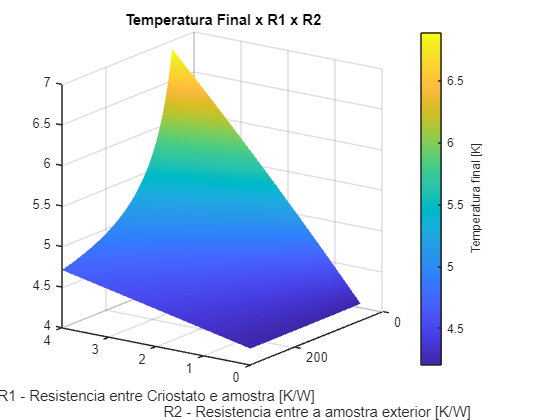

tempsu = surf(rr1,rr2,T_res.','EdgeColor','none','FaceColor','interp');
title('Temperatura Final x R1 x R2')
xlabel('R1 - Resistencia entre Criostato e amostra [K/W]')
ylabel('R2 - Resistencia entre a amostra exterior [K/W]')
c1 = colorbar;
c1.Label.String = 'Temperatura final [K]';
view(view_vec)

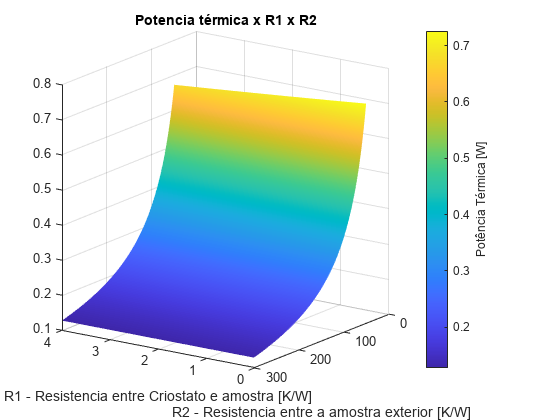

figure;
psu = surf(rr1,rr2,P_res.','EdgeColor','none','FaceColor','interp');
title('Potencia térmica x R1 x R2')
xlabel('R1 - Resistencia entre Criostato e amostra [K/W]')
ylabel('R2 - Resistencia entre a amostra exterior [K/W]')
view(view_vec)
c2 = colorbar;
c2.Label.String = 'Potência Térmica [W]';

figure;

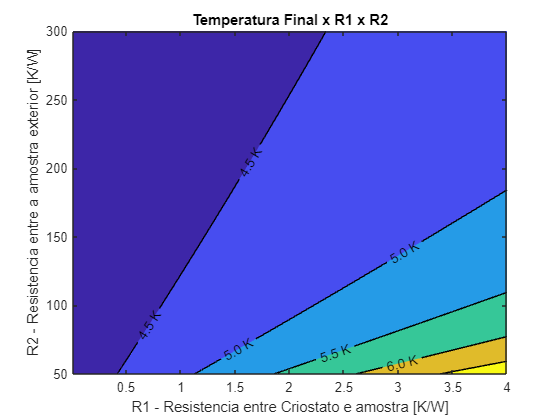

tempcon = contourf(rr1,rr2,T_res.','ShowText','on','EdgeColor','k',"LabelFormat","%0.1f K");
title('Temperatura Final x R1 x R2')
xlabel('R1 - Resistencia entre Criostato e amostra [K/W]')
ylabel('R2 - Resistencia entre a amostra exterior [K/W]')

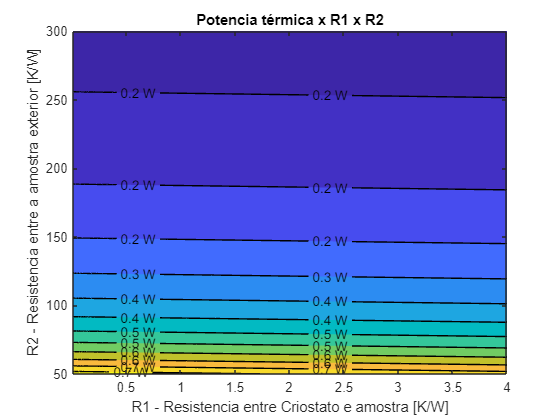

figure;
pcon = contourf(rr1,rr2,P_res.','ShowText','on','EdgeColor','k',"LabelFormat","%0.1f W");
title('Potencia térmica x R1 x R2')
xlabel('R1 - Resistencia entre Criostato e amostra [K/W]')
ylabel('R2 - Resistencia entre a amostra exterior [K/W]')

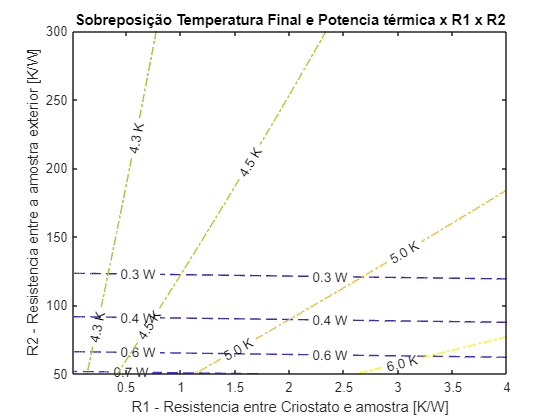

figure;
pc1 =contour(rr1,rr2,P_res.',[0.3 0.4 0.55 0.7 1.1],'ShowText','on','EdgeColor','flat',"LabelFormat","%0.1f W","LineStyle","--");
hold on
pc2 =contour(rr1,rr2,T_res.',[4.3 4.5 5 6 7 8 9],'ShowText','on','EdgeColor','flat',"LabelFormat","%0.1f K","LineStyle","-.");
hold on
title('Sobreposição Temperatura Final e Potencia térmica x R1 x R2')
xlabel('R1 - Resistencia entre Criostato e amostra [K/W]')
ylabel('R2 - Resistencia entre a amostra exterior [K/W]')

figure;

Vou avaliar a viabilidade p/ o uso de 6 flextures como suporte, A é o caso da vibração mecanica, B é o caso da condição termica


$$A : \frac{d^2}{l} > \frac{2\pi \cdot f_{min}^2 \cdot m}{Y} \\
B :\frac{d^2}{l} <\frac{4}{9 \cdot \bar k \cdot \pi \cdot R_{min} }$$


k = 0.278

k = 0.2780


R_min = 75

R_min = 75


f_min = 200

f_min = 200


m = 0.5

m = 0.5000


Y = 206.679 * 10^9

Y = 2.0668e+11




B = 4/(9 * k * pi * R_min)*1000

B = 6.7852


%rever a expressao B

A = 2 * pi * f_min^2 * m * Y^(-1) * 4^(-1)*1000

A = 1.5200e-04

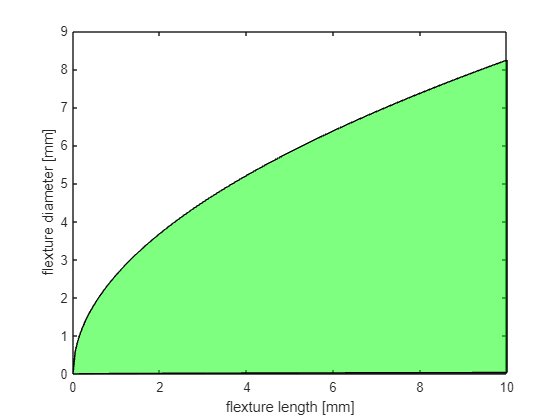

l = linspace(0,10,200);
d_m = sqrt(l*A);
d_t = sqrt(l*B);
plot(l,d_m,'y')
hold on
plot(l,d_t,'b')
hold on
xlabel("flexture length [mm]")
ylabel("flexture diameter [mm]")
patch([l fliplr(l)], [d_m fliplr(d_t)], 'g')
alpha(0.5)

figure;

Nova sujestao de modelo, usando 2 camadas de isolamento,(fazer figura no simulink)

Cvector = readtable("Material Properties/SS304-TC_SH_YM_YM_LE.tsv", "FileType", "text", 'Delimiter', '\t');
TC_c = Cvector(1:9,2);